# Multirotor Simulator

This tutorial shows how to define and simulate a multirotor robot and how to design a controller to control the attitude and the position of this robot.

In order to be able to run the simulator, first we should add its files to the path:

addpath('simulator');

Feel free to explore this directory to get familiar. The main scripts we will be playing with are `multirotor, simulation and controller.`

## Multirotor Definition

Let's define a new multirotor. We can define the multirotor by defining the arrangement of its arms (the angles of the arms locations with respect to the forward direction). The number of angles also defines how many rotors we will have in the multirotor. For example, if you want a quadrotor, you should choose 4 angles, but a hexarotor would need 6 angles.

Note that we assume NED frame, therefore the angles will be clockwise if you're loocking at the multirotor from the top. Feel free to change the default values:

RotorPlacementAngles = [45, 135, 225, 315];

Let's also define the directions of the rotor rotations (-1 is for clockwise and 1 is for counter-clockwise around Z. It's the same if you are looking from the top):

RotorRotationDirections = [-1, 1, -1, 1];

Good! Now let's construct our multirotor object from our definitions:

m = multirotor(RotorPlacementAngles, RotorRotationDirections)

m =   multirotor with properties:

             Rotors: {4×1 cell}
               Mass: 3
                  I: [3×3 double]
      PayloadRadius: 0.1500
    TotalSpeedLimit: 20
     VelocityLimits: [3×1 double]
    EulerRateLimits: [3×1 double]
        NumOfRotors: 4
       InitialState: [1×1 struct]
              State: [1×1 struct]
              I_inv: [3×3 double]


Feel free to explore the structure of the multirotor object. You will see that it has an array of Rotors that describes the specifications of the rotors. You can change the properties of the multirotor and each individual rotor. However, you would need to call `m.UpdateStructure()` function to recalculate the inertia tensor if you change the structure (e.g., angles, masses, lengths, etc.).

## Visualization

Now is time to see how your multirotor looks like:

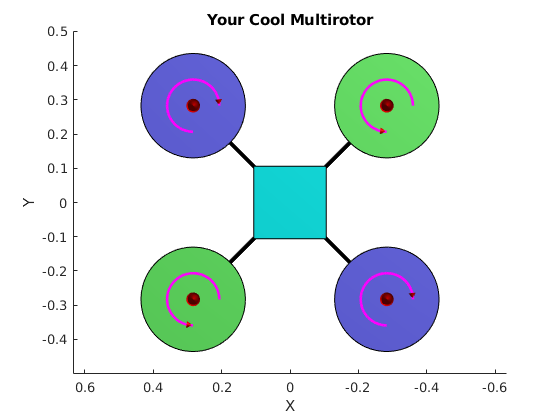

m.Visualize()

Remember that the front is the positive `X` direction.

Feel free to open the figure in a separate window (click on the button at the top-right of the figure when you move the mouse on it). You will be able to explore the structure in 3-D by choosing `Rotate 3D` from the `Tools` menu.

## Controller Definition

Similarly, we can define a new controller for our multirotor:

c = controller(m);

The structure of the controller is similar to the figure below:

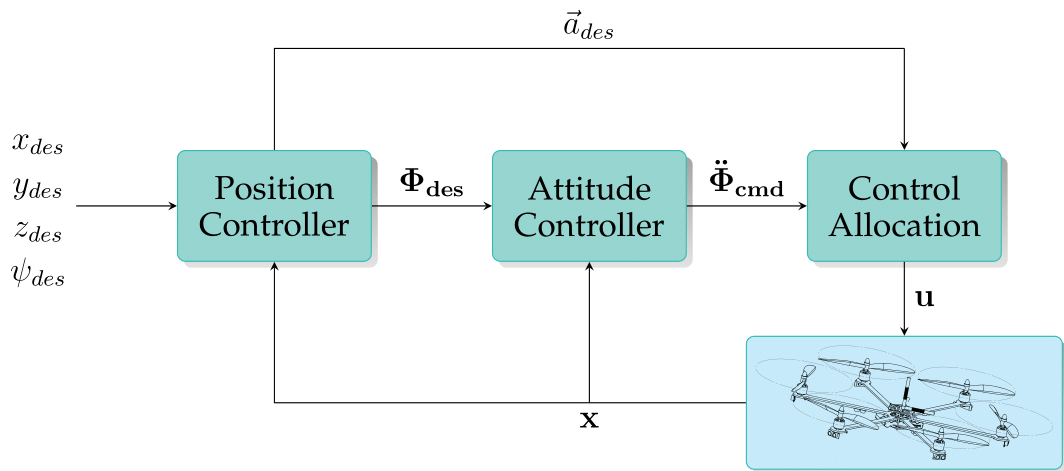

In the slides we talked about the modules and the inputs and outputs to our modules, but it wouldn't hurt to refresh the memory:

- The input to the multirotor (**u**) is a vector of the squared rotor speeds. Obviously, the vector should be the same size as the number of rotors.

- The output of the multirotor (**x**) is the current state of the multirotor. Feel free to explore `m.State` to see what information is provided by the multirotor.

- The Control Allocation module accepts the desired linear and angular accelerations and magically converts them to the rotor speeds for the multirotor. The conversion is mostly a mathematical calculation based on the multirotor's structure and we will not be focusing on it today, but feel free to explore how it works.

- The Attitude Controller module receives a desired attitude (i.e., roll, pitch and yaw) and calculates some amgular velocity that will change the multirotor's attitude to achieve the desired attitude. It is a PID controller that we will be tuning today.

- Finally, the Position Controller module receives the desired position and yaw and calculated the acceleration and the attitude that will help the multirotor to achieve those position and yaw. 

## Simulation Definition

We can define a simulation that will helps us with connecting our multirotor and controller, and can automate the time steps and the feedback loop for us. Let's first define the simulator:

sim = simulation(m, c);

We can set the total simulation time and the simulation time step size using `sim.TotalTime` and `sim.TimeStep` properties, respectively. Let's just change the simulation time from the default 5 seconds to 10 seconds and leave the rest as is for now:

sim.TotalTime = 10;

## Attitude Controller Tuning

Let's start with tuning the attitude controller P, I and D gains. We can set the gains as:

sim.Controller.AttitudeController.SetPID(1, 0, 1);

Each input gain can be a scalar (such as above example) where all the roll, pitch and yaw will get the same gains. Alternatively, the inputs can be 3-D vectors to provide different gains for roll, pitch and yaw. Finally, you can define the gains as 3x3 matrices that will be multiplied by the attitude's error 3-D vector. The same command above could be defined in this way:

`sim.Controller.AttitudeController.SetPID(eye(3), 0, ones(3, 1));`

Now let's set the initial state of our multirotor for tuning our attitude controller. We can do that using a command such as below:

`sim.Multirotor.SetInitialState(pos, vel, rpy, omega);`

For the purpose of tuning the attitude gains, we are only interested in the attitude initial input, so we can set the others as zero for now:

sim.Multirotor.SetInitialState(zeros(3, 1), zeros(3, 1), [10; 20; 0], zeros(3, 1));

Finally, let's simulate the our system and see how our attitude controller is working. 

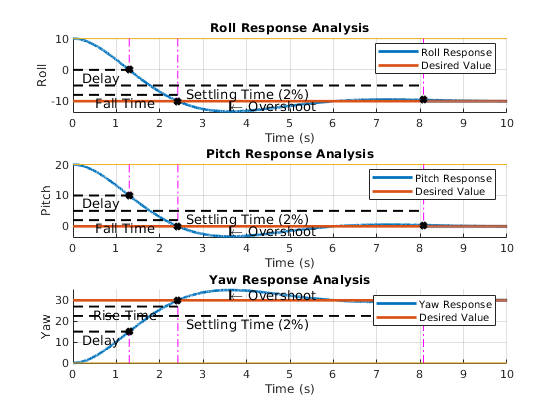

Analysis for response of Roll going from 10.00 to -10.00:
    Total Simulation Time: 10.000 (s)
    Simulation Time Step : 1.00 (ms)
    The system type is   : Underdamped
    Overshoot Magnitude  : 3.272
    Overshoot Percentage : 16.36 %
    Fall Time (0%-100%)  : 2.415 (s)
    Delay Time (0%-50%)  : 1.295 (s)
    Settling Time (2%)   : 8.076 (s)

Analysis for response of Pitch going from 20.00 to 0.00:
    Total Simulation Time: 10.000 (s)
    Simulation Time Step : 1.00 (ms)
    The system type is   : Underdamped
    Overshoot Magnitude  : 3.277
    Overshoot Percentage : 16.39 %
    Fall Time (0%-100%)  : 2.416 (s)
    Delay Time (0%-50%)  : 1.295 (s)
    Settling Time (2%)   : 8.079 (s)

Analysis for response of Yaw going from 0.00 to 30.00:
    Total Simulation Time: 10.000 (s)
    Simulation Time Step : 1.00 (ms)
    The system type is   : Underdamped
    Overshoot Magnitude  : 4.911
    Overshoot Percentage : 16.37 %
    Rise Time (0%-100%)  : 2.416 (s)
    Delay Time (0%-50%)

sim.SimulateAttitudeResponse([-10; 0; 30], true);

## Task #1: Tune it!

Tune the PID gains for the attitude controller above to get the best results that you can. In other words, try to minimize the unwanted effects such as overshoot and the different response times without causing motor saturation. I would recommend starting with only one of the signals (e.g., `Yaw`), tuning it, then tuning the others separately and at the end test all of them together.

The higher gain means the higher probability of motor saturations, but the lower gain generally means lower performance. Find the tradeoff. Start with only `P` gain and try to find a good response. Then increase the `D` gain until you are happy. Now go back to increasing `P` again and repeat the process interatively tuning `P` and `D` gains until you cannot make it better. You can skip tuning the `I` gain for now, but if you are interested you can experiment with that either. In other words, after finding your perfect `P` and `D` gains, slightly increase `I` until you see weird behavious or you cannot make it better. Then go back and find the best `P` and `D` gains again with the new `I` and repeat the whole process. 

To help you with seeing how the motors are behaving during your tuning process you can plot the motor speeds using this command:

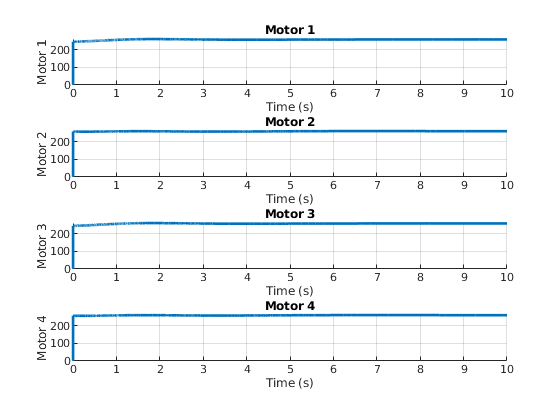

graphics.PlotSignalsByName(sim, 1, 'rpm', true);

Remember that the motor maximum speeds are not your only limit. There are other physical limitations such as maximum velocity and maximum Euler rate (you can find them in `multirotor` class). So, if you see a weird response, that means probably you have hit the limits.

You can also see other plots. Just use a recognizable name and system will find out what signal you want. For example you may be interested in the Euler rates as well as rotor saturations (you can check the `GetField` function in the `state_collection` class to see what strings to use for other signals, if interested):

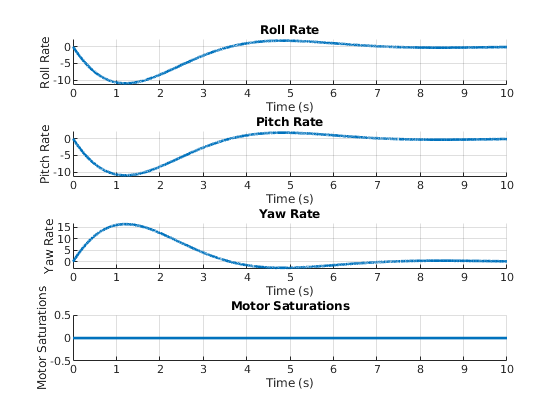

graphics.PlotSignalsByName(sim, 1, {'euler rate', 'saturations'}, true);

Good luck!